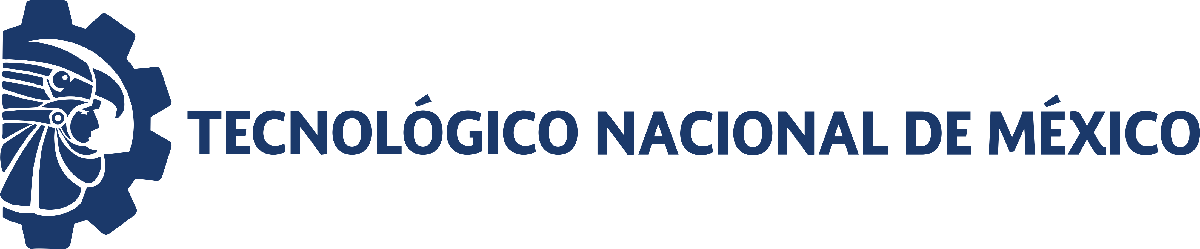                                 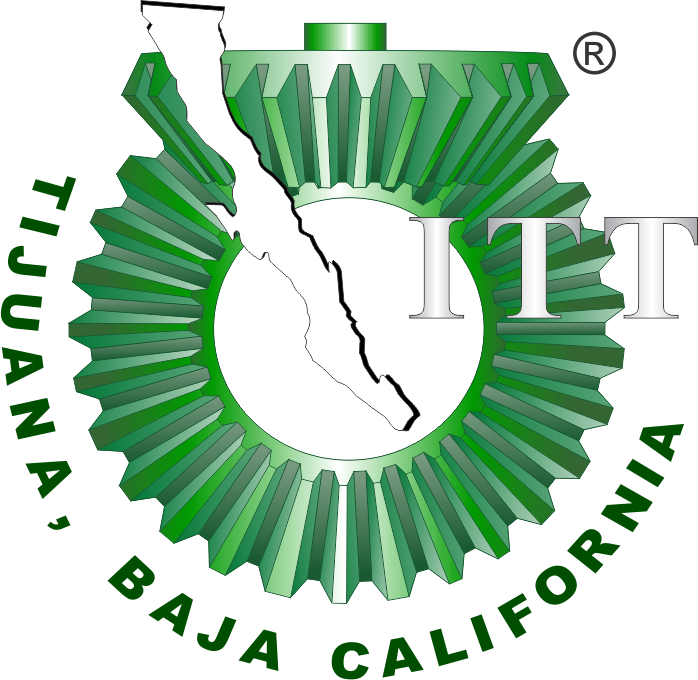

# Práctica dos: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

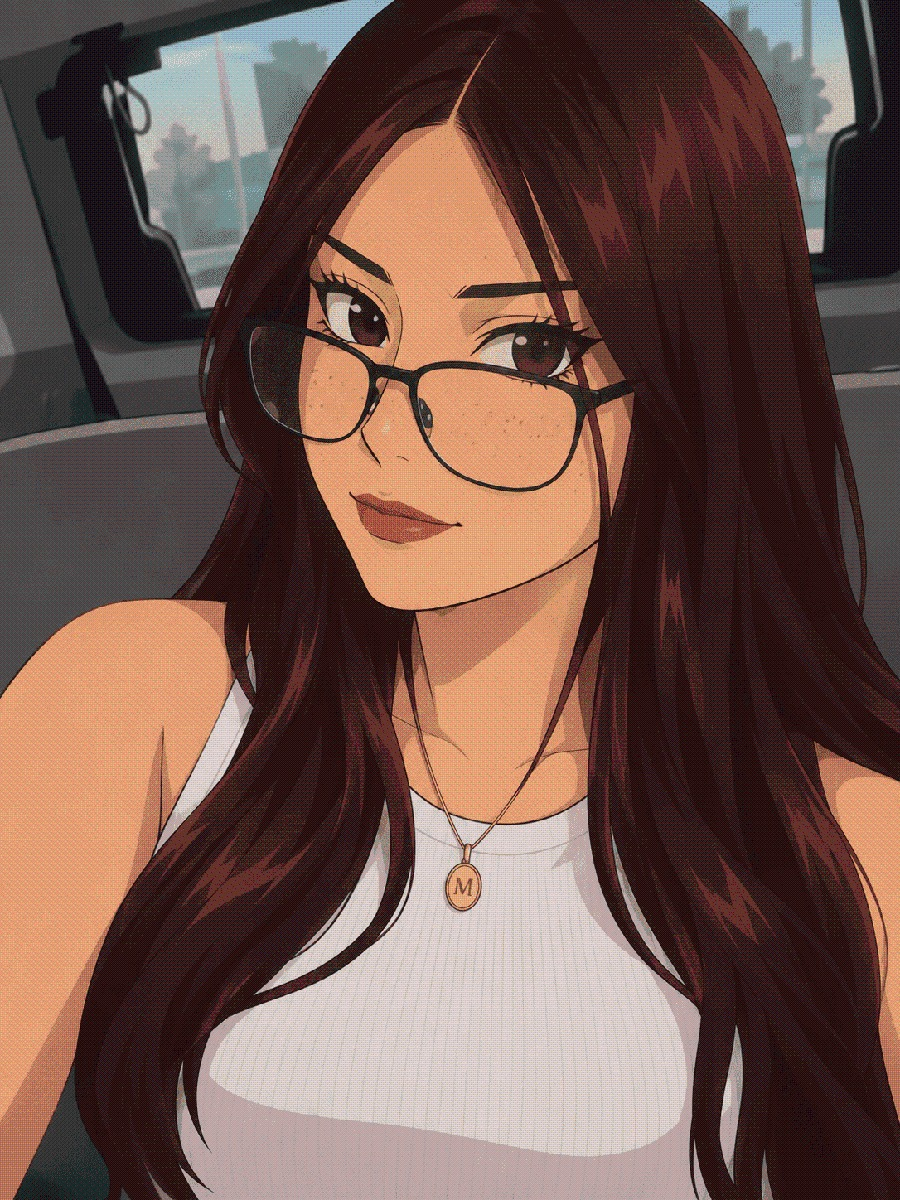

Nombre del alumno: Mildred Angel Torales

Número de control: 23212731

Correo institucional: l23212731**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('Practica2_MSF1_MAT')
parameters.StopTime = '15';
parameters.Solver = 'ode15s';
parameters.MaxStep = '1e-2';
x= sim('Practica2_MSF1_MAT',parameters);
writematrix(x.Pa,'signal.xlsx');

## Sistema normotenso

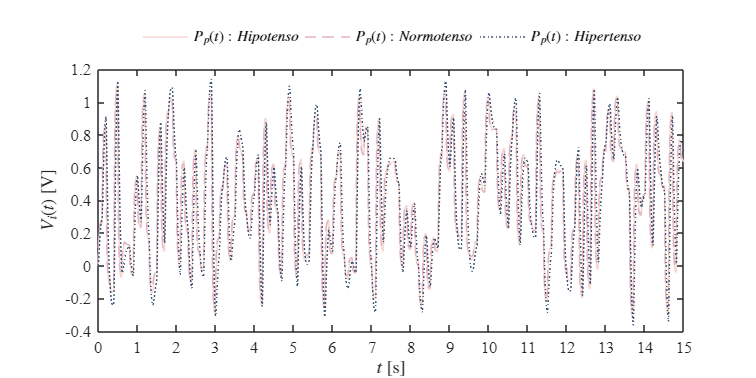

plotsignals(x.t,x.PpL,x.PpN,x.PpH,'Normotenso')

## Sistema hipotenso

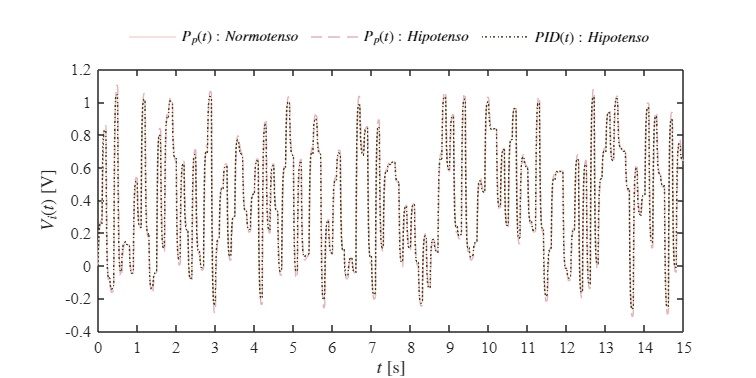


plotsignals(x.t,x.PpN,x.PpL,x.PIDL,'Hipotenso')

## Sistema Hipertenso

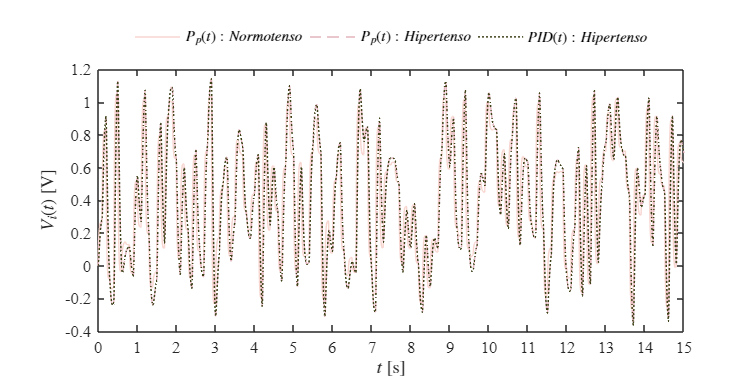

plotsignals(x.t,x.PpN,x.PpH,x.PIDH,'Hipertenso')

## Funcion: Respuesta de simulacion

function plotsignals(t,x1,x2,x3,caso)
    set(figure(),'color','w')
    set(gcf,'units','inches','position',[1,1,7,3.5])
    set(gca,'fontname','times new roman','fontsize',11)
    hold on; grid off; box on;
    clr1 = [247, 214, 208]/255;
    clr2 = [226, 180, 189]/255;
    clr3 = [62, 88, 121]/255;
    clr4 = [65, 67, 27]/255;


    if caso == "Normotenso"
        plot(t,x1,'-','LineWidth',0.25,'Color',clr1)
        plot(t,x2,'--','LineWidth',0.25,'Color',clr2)
        plot(t,x3,':','LineWidth',0.25,'Color',clr3)
        L = legend('$P_p(t):Hipotenso$','$P_p(t):Normotenso$','$P_p(t):Hipertenso$');
    elseif caso == "Hipotenso"
        plot(t,x1,'-','LineWidth',0.25,'Color',clr1)
        plot(t,x2,'--','LineWidth',0.25,'Color',clr2)
        plot(t,x3,':','LineWidth',1,'Color',clr4)
        L = legend('$P_p(t):Normotenso$','$P_p(t):Hipotenso$','$PID(t):Hipotenso$');
    elseif caso == "Hipertenso"
        plot(t,x1,'-','LineWidth',0.25,'Color',clr1)
        plot(t,x2,'--','LineWidth',0.25,'Color',clr2)
        plot(t,x3,':','LineWidth',1,'Color',clr4)
        L = legend('$P_p(t):Normotenso$','$P_p(t):Hipertenso$','$PID(t):Hipertenso$');
    end

    set(L,'interpreter','latex','location','northoutside','orientation','horizontal', 'box','off')
    xlabel('$t$ [s]','interpreter','latex')
    ylabel('$V_i(t)$ [V]','interpreter','latex')

    xlim([0 15]); xticks(0:1:15)
    ylim([-0.4 1.2]); yticks(-0.4:0.2:1.2)
  
end
    